clear

**Descrivi l'ordine dei dati:**

Nei dati, la prima riga è il tempo, la seconda è $\theta$, la terza è $\alpha$ la quatra, se c'è, è la tensione in ingresso. (tra una colonna e l'altra sono passati 2 ms)

Il seguente script è stato fatto con il seguente codice c++:

#include <iostream>

using namespace std;

int main()

{

    int first_exp = 71;

    int last_exp = 84;

    char cartella[] = "Compensator_Alberto";

    cout << "step_size = 0.002;\n\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "% Esperimento: " << i << "\n\n";

        cout << "% Estraggo i dati dal file dell'esperimento\n";

        cout << "esp" << i << "_struct = load('esp" << i << "');" << "\n";

        cout << "esp" << i << " = cell2mat(struct2cell(esp" << i << "_struct));\n";

        cout << "t_esp" << i << " = esp" << i << "(1,:);\n";

        cout << "voltage_esp" << i << " = esp" << i << "(2,:);\n";

        cout << "theta_esp" << i << " = esp" << i << "(3,:);\n";

        cout << "alpha_esp" << i << " = esp" << i << "(4,:);\n";

        cout << "theta_ref_esp" << i << " = esp" << i << "(5,:);\n";

        cout << "% Calcolo le velocità angolari:\n";

        cout << "theta_d_esp" << i << " = diff(theta_esp" << i << ")/step_size;\n";

        cout << "alpha_d_esp" << i << " = diff(alpha_esp" << i << ")/step_size;\n% Plot\n";

        // Grafico della tensione

        cout << "plot(t_esp" << i << ",voltage_esp" << i << ")\n";

        cout << "title('V')\ngrid(\"on\")\n";

        cout << "\n";

        // Grafico di theta

        cout << "plot(t_esp" << i << ",theta_esp" << i << ")\n";

        cout << "hold on\nplot(t_esp" << i << ",theta_ref_esp" << i << ")\nhold off\n";

        cout << "title('\\theta')\ngrid(\"on\")\n";

        // velocità di theta

        cout << "theta_d_esp" << i << "(1,length(theta_d_esp" << i << ")+1) = 0;\n";

        cout << "plot(t_esp" << i << ",theta_d_esp" << i << ")\n";

        cout << "title('$\\dot{\\theta}$','Interpreter','latex')\ngrid(\"on\")\n";

        // Grafico di alpha

        cout << "plot(t_esp" << i << ",alpha_esp" << i << ")\n";

        cout << "title('\\alpha')\ngrid(\"on\")\n";

        // velocità di alpha

        cout << "alpha_d_esp" << i << "(1,length(alpha_d_esp" << i << ")+1) = 0;\n";

        cout << "plot(t_esp" << i << ",alpha_d_esp" << i << ")\n";

        cout << "title('$\\dot{\\alpha}$','Interpreter','latex')\ngrid(\"on\")\n";

    }

    cout << "% Salvare tutte le varabili\n";

    // Per salvare alpha_d_esp:

    cout << "cd ..\\" << cartella << "\\alpha_d_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('alpha_d_esp" << i << "','alpha_d_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    // Per salvare alpha_esp:

    cout << "cd ..\\" << cartella << "\\alpha_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('alpha_esp" << i << "','alpha_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    // Per salvare theta_d_esp:

    cout << "cd ..\\" << cartella << "\\theta_d_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('theta_d_esp" << i << "','theta_d_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    // Per salvare theta_esp:

    cout << "cd ..\\" << cartella << "\\theta_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('theta_esp" << i << "','theta_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    // Per salvare t_esp:

    cout << "cd ..\\" << cartella << "\\t_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('t_esp" << i << "','t_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    // Per salvare voltage_esp:

    cout << "cd ..\\" << cartella << "\\voltage_esp\n";

    for (int i = first_exp; i < last_exp+1; i++) {

        cout << "save('voltage_esp" << i << "','voltage_esp" << i << "')\n";   

    }

    cout << "cd ..\n";

    return 0;

}

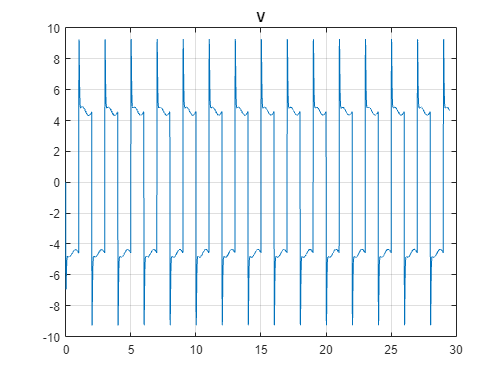

step_size = 0.002;

% Esperimento: 71

% Estraggo i dati dal file dell'esperimento
esp71_struct = load('esp71');
esp71 = cell2mat(struct2cell(esp71_struct));
t_esp71 = esp71(1,:);
voltage_esp71 = esp71(2,:);
theta_esp71 = esp71(3,:);
alpha_esp71 = esp71(4,:);
theta_ref_esp71 = esp71(5,:);
% Calcolo le velocità angolari:
theta_d_esp71 = diff(theta_esp71)/step_size;
alpha_d_esp71 = diff(alpha_esp71)/step_size;
% Plot
plot(t_esp71,voltage_esp71)
title('V')
grid("on")

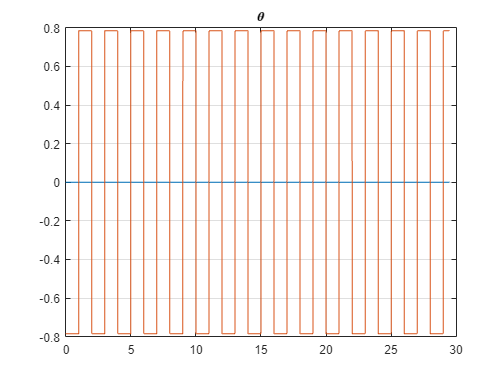


plot(t_esp71,theta_esp71)
hold on
plot(t_esp71,theta_ref_esp71)
hold off
title('\theta')
grid("on")

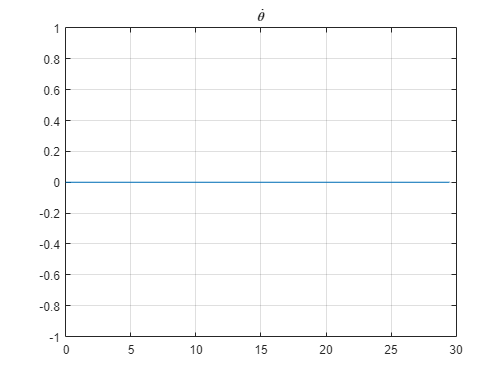

theta_d_esp71(1,length(theta_d_esp71)+1) = 0;
plot(t_esp71,theta_d_esp71)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

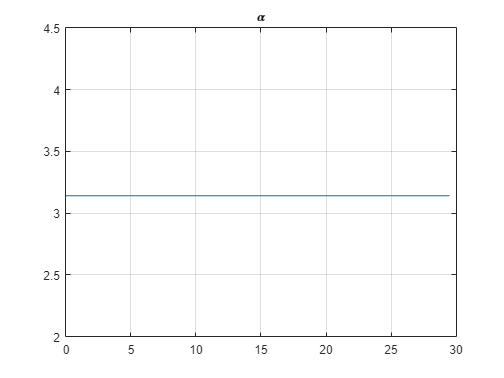

plot(t_esp71,alpha_esp71)
title('\alpha')
grid("on")

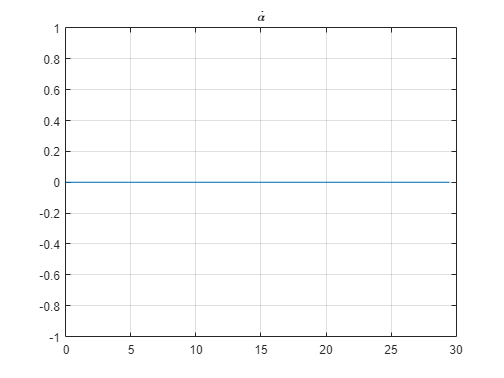

alpha_d_esp71(1,length(alpha_d_esp71)+1) = 0;
plot(t_esp71,alpha_d_esp71)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

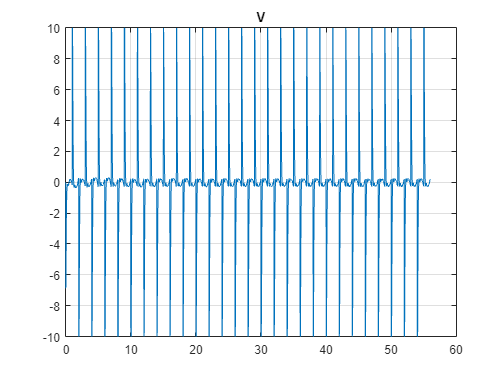

% Esperimento: 72

% Estraggo i dati dal file dell'esperimento
esp72_struct = load('esp72');
esp72 = cell2mat(struct2cell(esp72_struct));
t_esp72 = esp72(1,:);
voltage_esp72 = esp72(2,:);
theta_esp72 = esp72(3,:);
alpha_esp72 = esp72(4,:);
theta_ref_esp72 = esp72(5,:);
% Calcolo le velocità angolari:
theta_d_esp72 = diff(theta_esp72)/step_size;
alpha_d_esp72 = diff(alpha_esp72)/step_size;
% Plot
plot(t_esp72,voltage_esp72)
title('V')
grid("on")

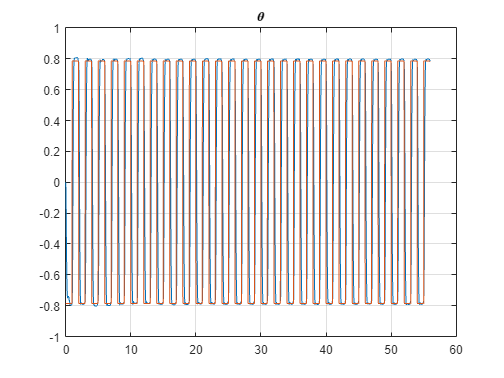


plot(t_esp72,theta_esp72)
hold on
plot(t_esp72,theta_ref_esp72)
hold off
title('\theta')
grid("on")

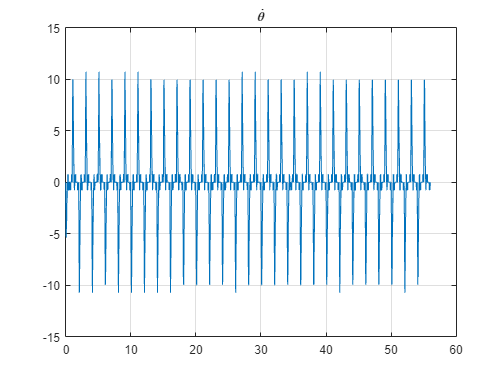

theta_d_esp72(1,length(theta_d_esp72)+1) = 0;
plot(t_esp72,theta_d_esp72)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

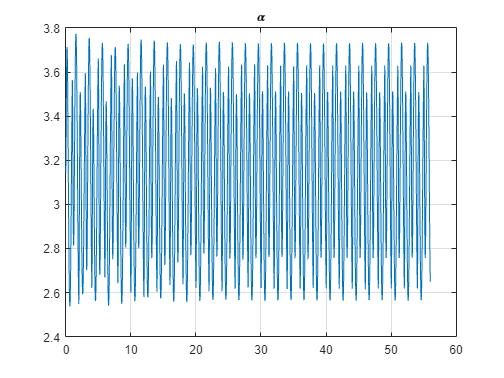

plot(t_esp72,alpha_esp72)
title('\alpha')
grid("on")

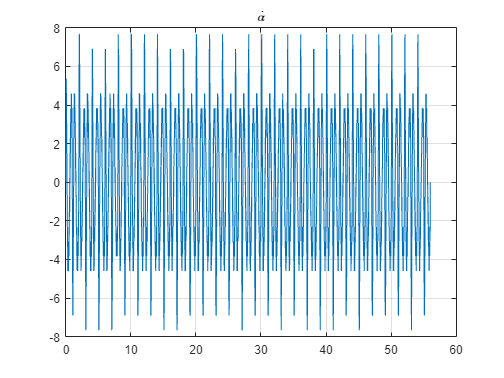

alpha_d_esp72(1,length(alpha_d_esp72)+1) = 0;
plot(t_esp72,alpha_d_esp72)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

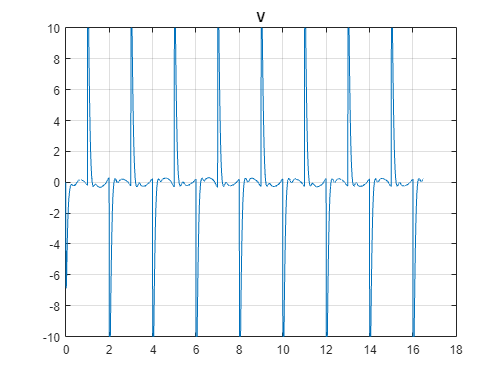

% Esperimento: 73

% Estraggo i dati dal file dell'esperimento
esp73_struct = load('esp73');
esp73 = cell2mat(struct2cell(esp73_struct));
t_esp73 = esp73(1,:);
voltage_esp73 = esp73(2,:);
theta_esp73 = esp73(3,:);
alpha_esp73 = esp73(4,:);
theta_ref_esp73 = esp73(5,:);
% Calcolo le velocità angolari:
theta_d_esp73 = diff(theta_esp73)/step_size;
alpha_d_esp73 = diff(alpha_esp73)/step_size;
% Plot
plot(t_esp73,voltage_esp73)
title('V')
grid("on")

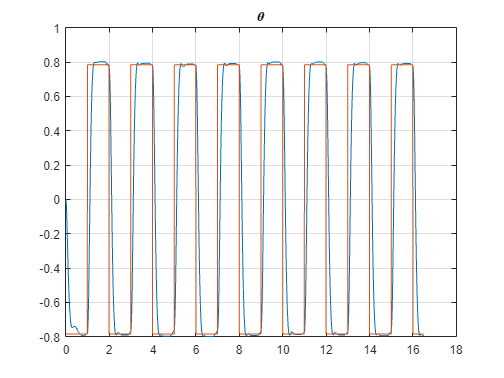


plot(t_esp73,theta_esp73)
hold on
plot(t_esp73,theta_ref_esp73)
hold off
title('\theta')
grid("on")

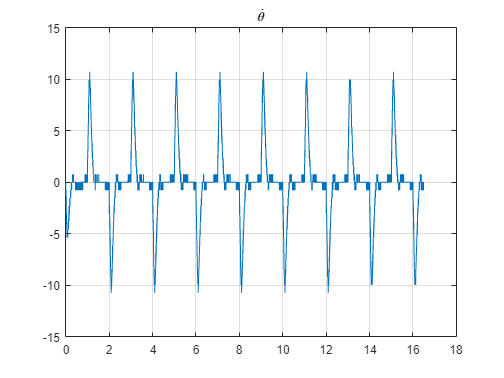

theta_d_esp73(1,length(theta_d_esp73)+1) = 0;
plot(t_esp73,theta_d_esp73)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

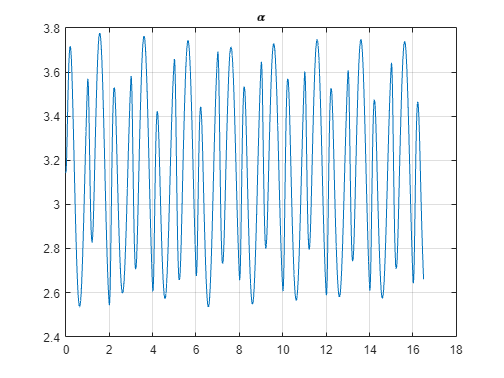

plot(t_esp73,alpha_esp73)
title('\alpha')
grid("on")

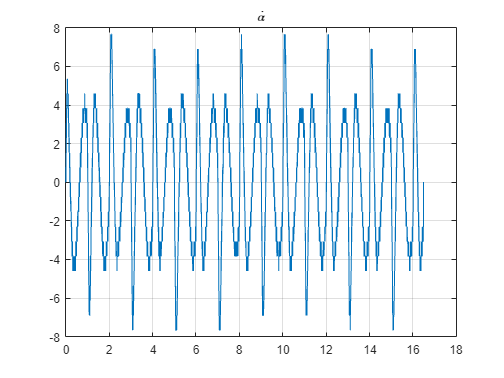

alpha_d_esp73(1,length(alpha_d_esp73)+1) = 0;
plot(t_esp73,alpha_d_esp73)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

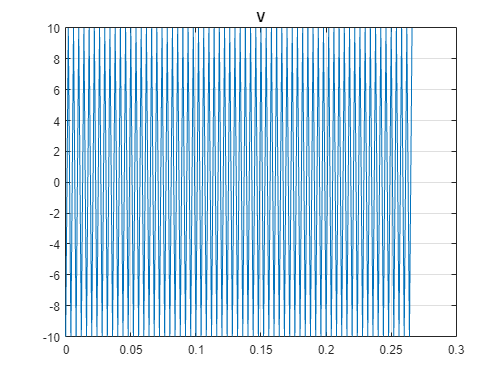

% Esperimento: 74

% Estraggo i dati dal file dell'esperimento
esp74_struct = load('esp74');
esp74 = cell2mat(struct2cell(esp74_struct));
t_esp74 = esp74(1,:);
voltage_esp74 = esp74(2,:);
theta_esp74 = esp74(3,:);
alpha_esp74 = esp74(4,:);
theta_ref_esp74 = esp74(5,:);
% Calcolo le velocità angolari:
theta_d_esp74 = diff(theta_esp74)/step_size;
alpha_d_esp74 = diff(alpha_esp74)/step_size;
% Plot
plot(t_esp74,voltage_esp74)
title('V')
grid("on")

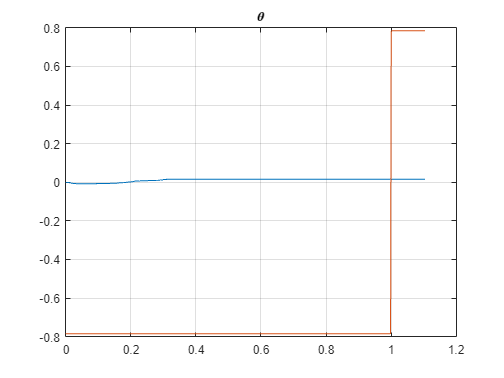


plot(t_esp74,theta_esp74)
hold on
plot(t_esp74,theta_ref_esp74)
hold off
title('\theta')
grid("on")

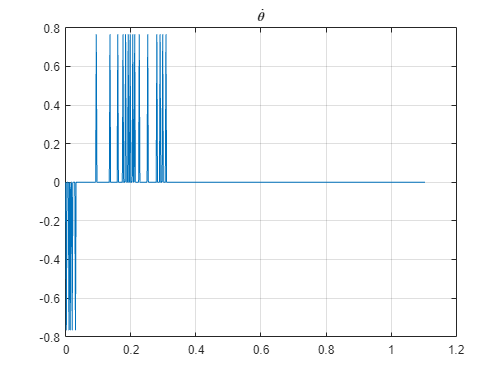

theta_d_esp74(1,length(theta_d_esp74)+1) = 0;
plot(t_esp74,theta_d_esp74)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

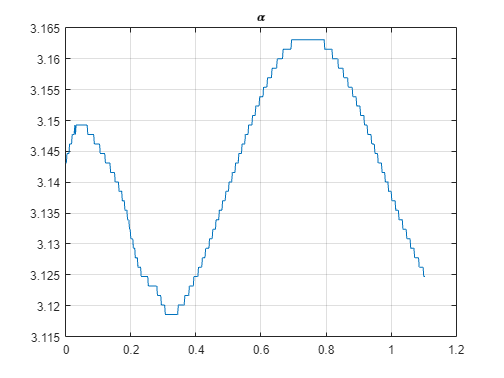

plot(t_esp74,alpha_esp74)
title('\alpha')
grid("on")

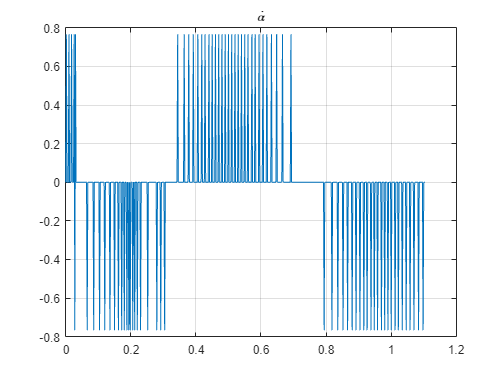

alpha_d_esp74(1,length(alpha_d_esp74)+1) = 0;
plot(t_esp74,alpha_d_esp74)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

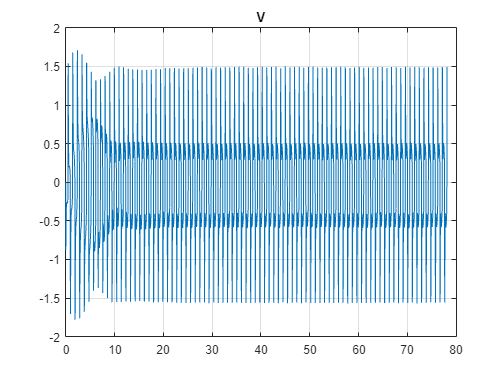

% Esperimento: 75

% Estraggo i dati dal file dell'esperimento
esp75_struct = load('esp75');
esp75 = cell2mat(struct2cell(esp75_struct));
t_esp75 = esp75(1,:);
voltage_esp75 = esp75(2,:);
theta_esp75 = esp75(3,:);
alpha_esp75 = esp75(4,:);
theta_ref_esp75 = esp75(5,:);
% Calcolo le velocità angolari:
theta_d_esp75 = diff(theta_esp75)/step_size;
alpha_d_esp75 = diff(alpha_esp75)/step_size;
% Plot
plot(t_esp75,voltage_esp75)
title('V')
grid("on")

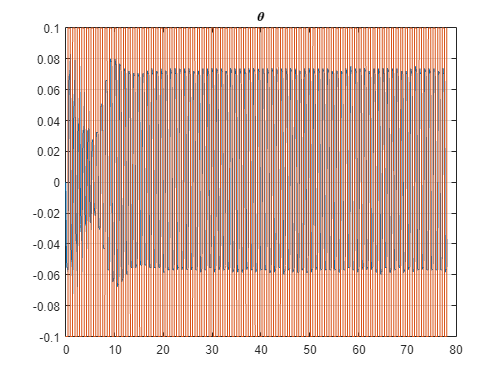


plot(t_esp75,theta_esp75)
hold on
plot(t_esp75,theta_ref_esp75)
hold off
title('\theta')
grid("on")

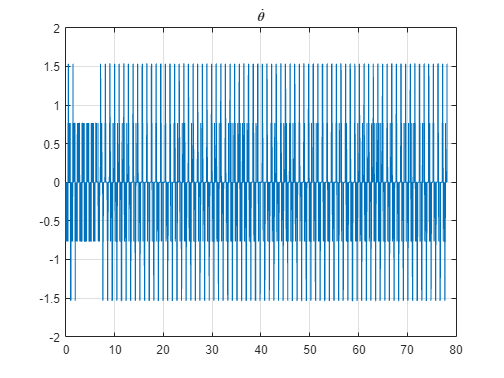

theta_d_esp75(1,length(theta_d_esp75)+1) = 0;
plot(t_esp75,theta_d_esp75)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

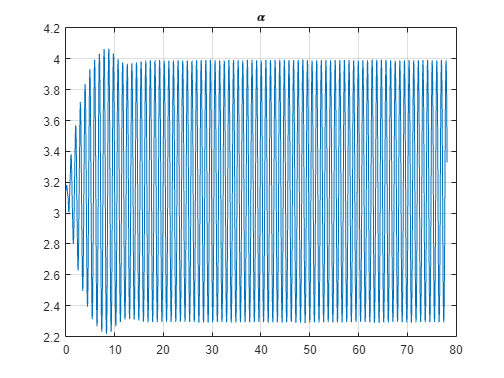

plot(t_esp75,alpha_esp75)
title('\alpha')
grid("on")

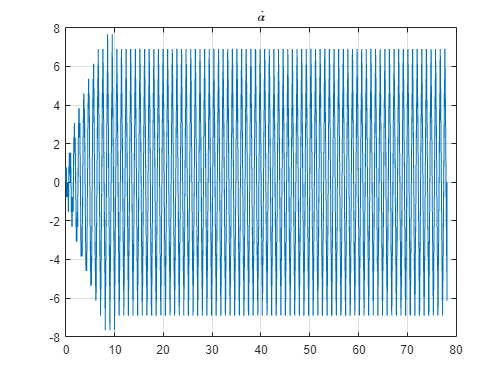

alpha_d_esp75(1,length(alpha_d_esp75)+1) = 0;
plot(t_esp75,alpha_d_esp75)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

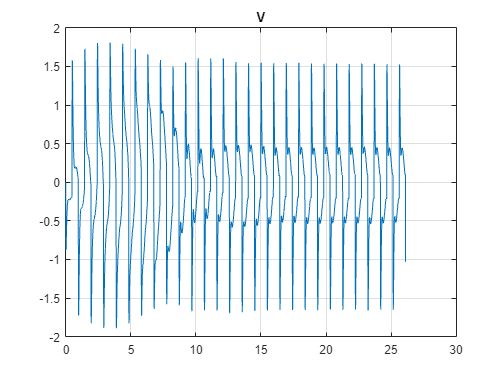

% Esperimento: 76

% Estraggo i dati dal file dell'esperimento
esp76_struct = load('esp76');
esp76 = cell2mat(struct2cell(esp76_struct));
t_esp76 = esp76(1,:);
voltage_esp76 = esp76(2,:);
theta_esp76 = esp76(3,:);
alpha_esp76 = esp76(4,:);
theta_ref_esp76 = esp76(5,:);
% Calcolo le velocità angolari:
theta_d_esp76 = diff(theta_esp76)/step_size;
alpha_d_esp76 = diff(alpha_esp76)/step_size;
% Plot
plot(t_esp76,voltage_esp76)
title('V')
grid("on")

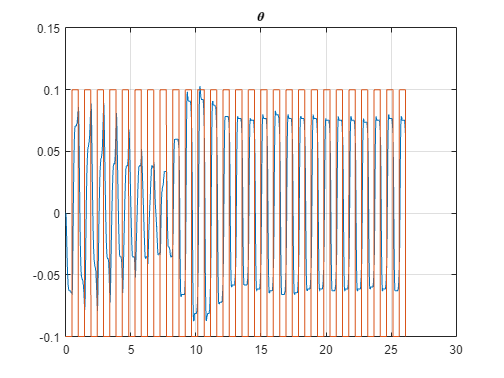


plot(t_esp76,theta_esp76)
hold on
plot(t_esp76,theta_ref_esp76)
hold off
title('\theta')
grid("on")

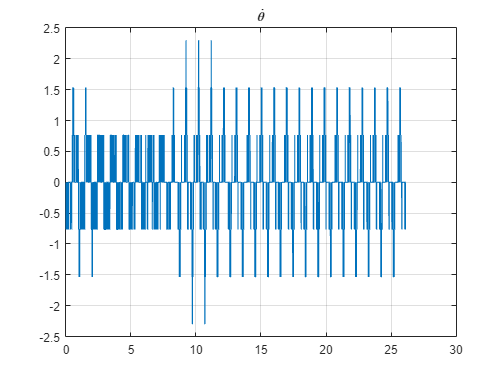

theta_d_esp76(1,length(theta_d_esp76)+1) = 0;
plot(t_esp76,theta_d_esp76)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

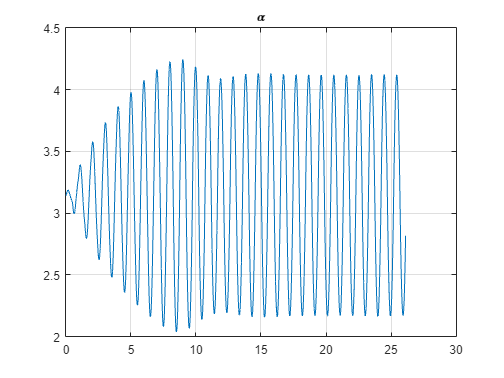

plot(t_esp76,alpha_esp76)
title('\alpha')
grid("on")

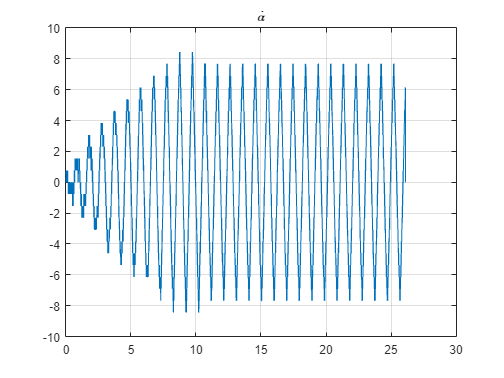

alpha_d_esp76(1,length(alpha_d_esp76)+1) = 0;
plot(t_esp76,alpha_d_esp76)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

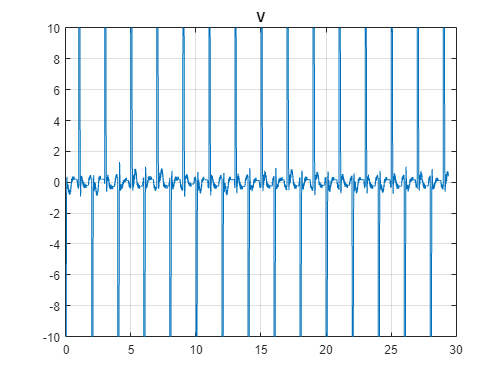

% Esperimento: 77

% Estraggo i dati dal file dell'esperimento
esp77_struct = load('esp77');
esp77 = cell2mat(struct2cell(esp77_struct));
t_esp77 = esp77(1,:);
voltage_esp77 = esp77(2,:);
theta_esp77 = esp77(3,:);
alpha_esp77 = esp77(4,:);
theta_ref_esp77 = esp77(5,:);
% Calcolo le velocità angolari:
theta_d_esp77 = diff(theta_esp77)/step_size;
alpha_d_esp77 = diff(alpha_esp77)/step_size;
% Plot
plot(t_esp77,voltage_esp77)
title('V')
grid("on")

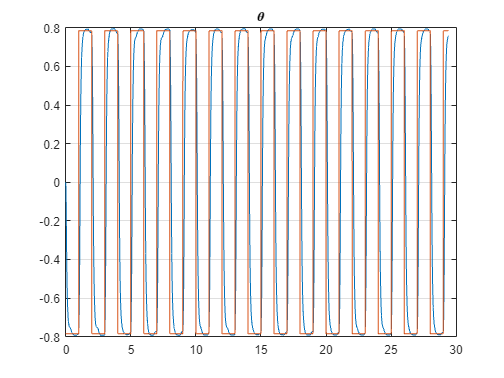


plot(t_esp77,theta_esp77)
hold on
plot(t_esp77,theta_ref_esp77)
hold off
title('\theta')
grid("on")

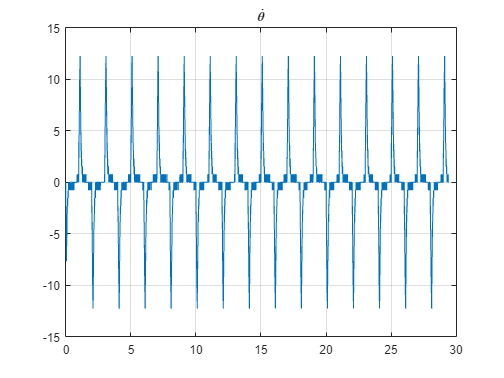

theta_d_esp77(1,length(theta_d_esp77)+1) = 0;
plot(t_esp77,theta_d_esp77)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

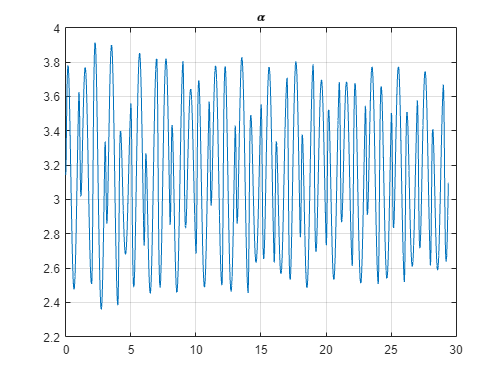

plot(t_esp77,alpha_esp77)
title('\alpha')
grid("on")

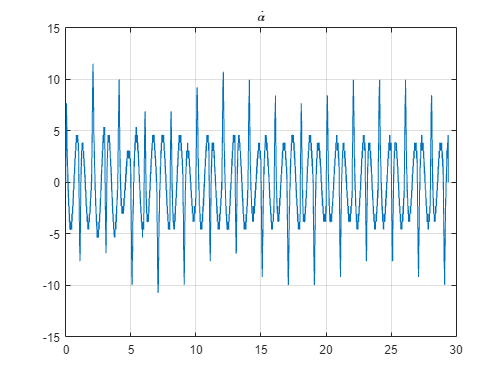

alpha_d_esp77(1,length(alpha_d_esp77)+1) = 0;
plot(t_esp77,alpha_d_esp77)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

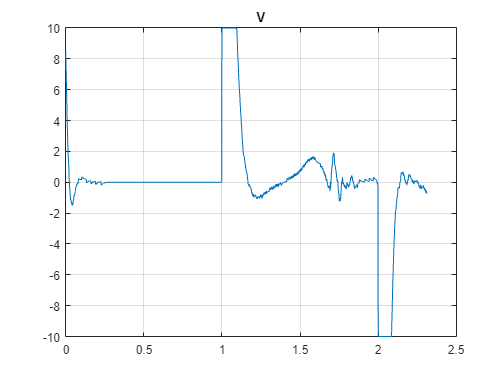

% Esperimento: 78

% Estraggo i dati dal file dell'esperimento
esp78_struct = load('esp78');
esp78 = cell2mat(struct2cell(esp78_struct));
t_esp78 = esp78(1,:);
voltage_esp78 = esp78(2,:);
theta_esp78 = esp78(3,:);
alpha_esp78 = esp78(4,:);
theta_ref_esp78 = esp78(5,:);
% Calcolo le velocità angolari:
theta_d_esp78 = diff(theta_esp78)/step_size;
alpha_d_esp78 = diff(alpha_esp78)/step_size;
% Plot
plot(t_esp78,voltage_esp78)
title('V')
grid("on")

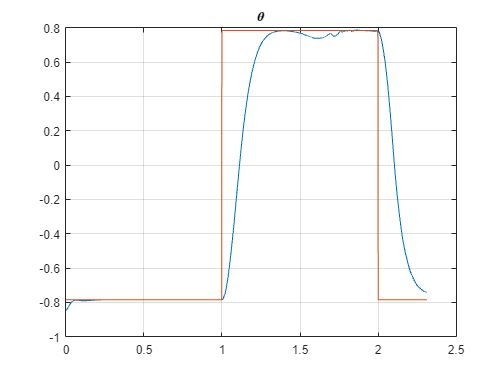


plot(t_esp78,theta_esp78)
hold on
plot(t_esp78,theta_ref_esp78)
hold off
title('\theta')
grid("on")

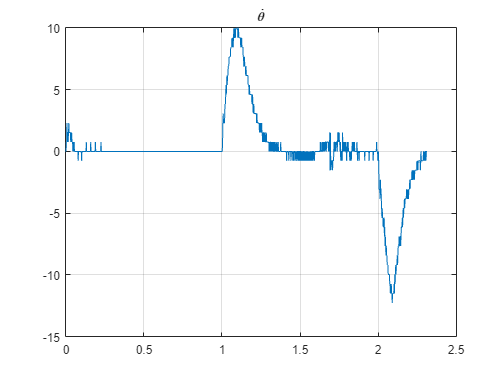

theta_d_esp78(1,length(theta_d_esp78)+1) = 0;
plot(t_esp78,theta_d_esp78)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

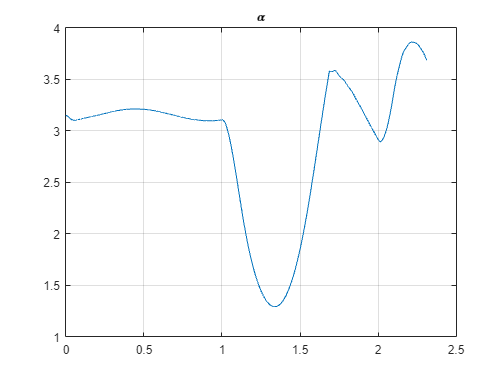

plot(t_esp78,alpha_esp78)
title('\alpha')
grid("on")

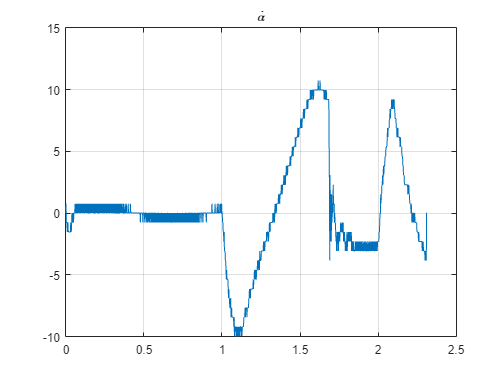

alpha_d_esp78(1,length(alpha_d_esp78)+1) = 0;
plot(t_esp78,alpha_d_esp78)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

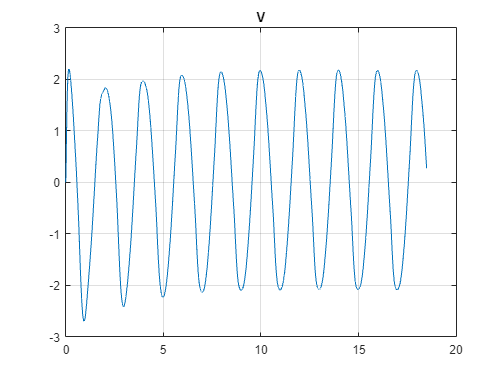

% Esperimento: 79

% Estraggo i dati dal file dell'esperimento
esp79_struct = load('esp79');
esp79 = cell2mat(struct2cell(esp79_struct));
t_esp79 = esp79(1,:);
voltage_esp79 = esp79(2,:);
theta_esp79 = esp79(3,:);
alpha_esp79 = esp79(4,:);
theta_ref_esp79 = esp79(5,:);
% Calcolo le velocità angolari:
theta_d_esp79 = diff(theta_esp79)/step_size;
alpha_d_esp79 = diff(alpha_esp79)/step_size;
% Plot
plot(t_esp79,voltage_esp79)
title('V')
grid("on")

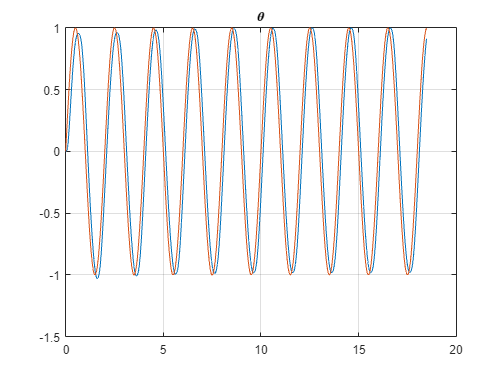


plot(t_esp79,theta_esp79)
hold on
plot(t_esp79,theta_ref_esp79)
hold off
title('\theta')
grid("on")

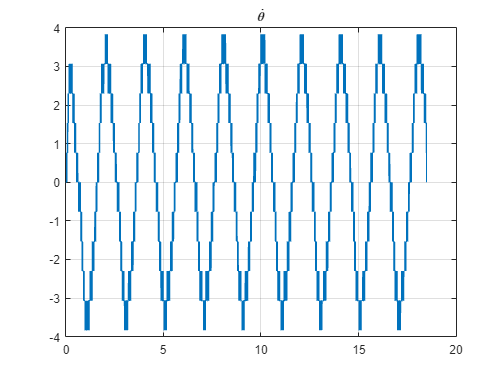

theta_d_esp79(1,length(theta_d_esp79)+1) = 0;
plot(t_esp79,theta_d_esp79)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

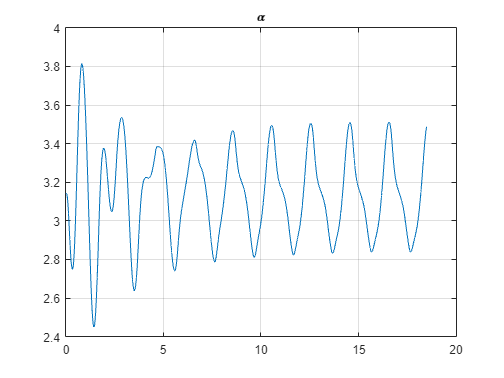

plot(t_esp79,alpha_esp79)
title('\alpha')
grid("on")

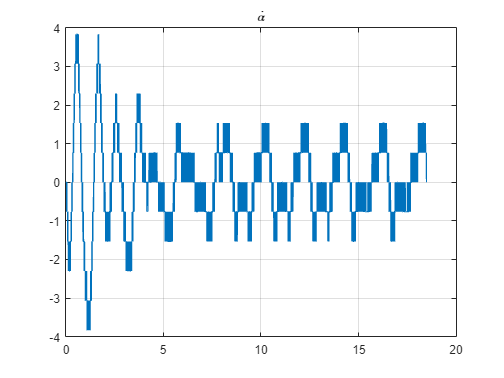

alpha_d_esp79(1,length(alpha_d_esp79)+1) = 0;
plot(t_esp79,alpha_d_esp79)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

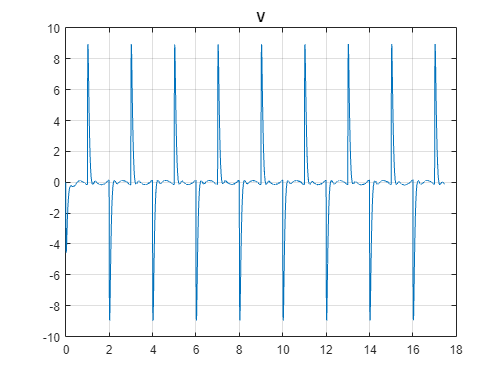

% Esperimento: 80

% Estraggo i dati dal file dell'esperimento
esp80_struct = load('esp80');
esp80 = cell2mat(struct2cell(esp80_struct));
t_esp80 = esp80(1,:);
voltage_esp80 = esp80(2,:);
theta_esp80 = esp80(3,:);
alpha_esp80 = esp80(4,:);
theta_ref_esp80 = esp80(5,:);
% Calcolo le velocità angolari:
theta_d_esp80 = diff(theta_esp80)/step_size;
alpha_d_esp80 = diff(alpha_esp80)/step_size;
% Plot
plot(t_esp80,voltage_esp80)
title('V')
grid("on")

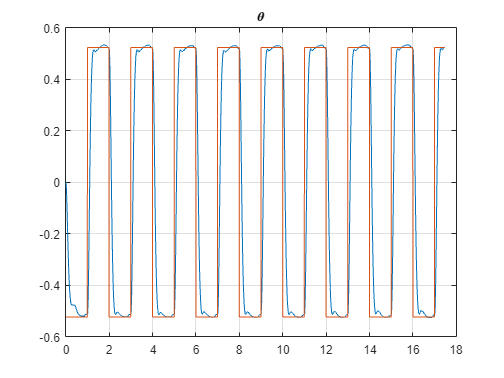


plot(t_esp80,theta_esp80)
hold on
plot(t_esp80,theta_ref_esp80)
hold off
title('\theta')
grid("on")

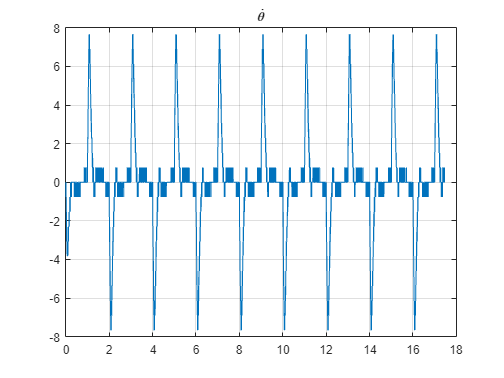

theta_d_esp80(1,length(theta_d_esp80)+1) = 0;
plot(t_esp80,theta_d_esp80)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

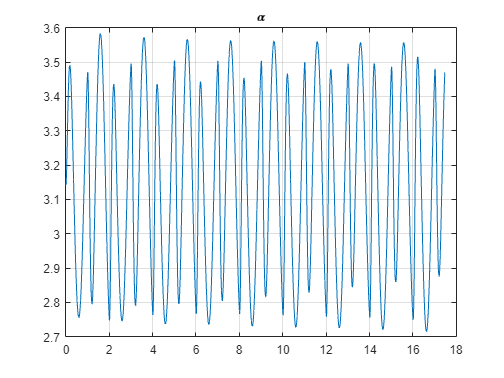

plot(t_esp80,alpha_esp80)
title('\alpha')
grid("on")

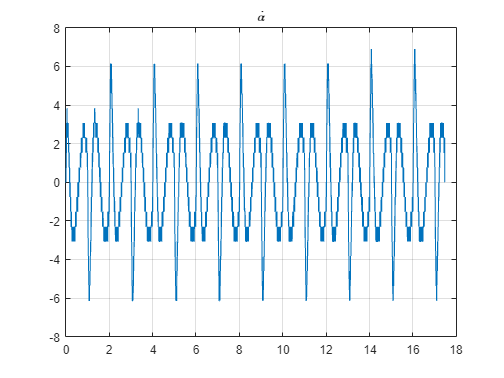

alpha_d_esp80(1,length(alpha_d_esp80)+1) = 0;
plot(t_esp80,alpha_d_esp80)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

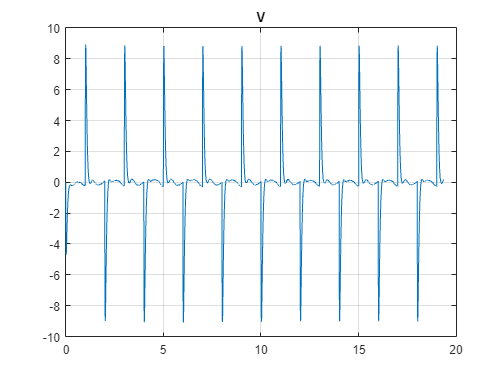

% Esperimento: 81

% Estraggo i dati dal file dell'esperimento
esp81_struct = load('esp81');
esp81 = cell2mat(struct2cell(esp81_struct));
t_esp81 = esp81(1,:);
voltage_esp81 = esp81(2,:);
theta_esp81 = esp81(3,:);
alpha_esp81 = esp81(4,:);
theta_ref_esp81 = esp81(5,:);
% Calcolo le velocità angolari:
theta_d_esp81 = diff(theta_esp81)/step_size;
alpha_d_esp81 = diff(alpha_esp81)/step_size;
% Plot
plot(t_esp81,voltage_esp81)
title('V')
grid("on")

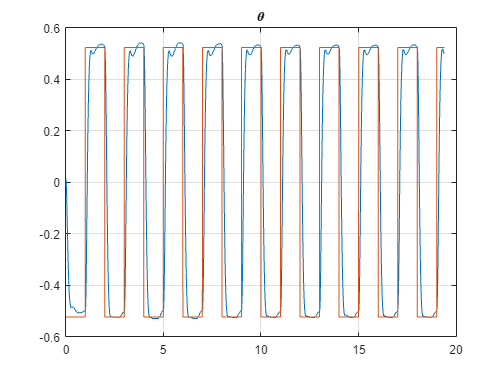


plot(t_esp81,theta_esp81)
hold on
plot(t_esp81,theta_ref_esp81)
hold off
title('\theta')
grid("on")

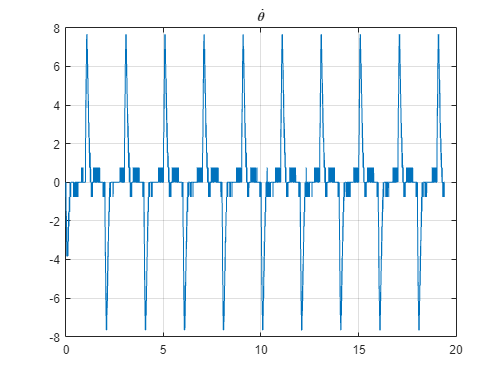

theta_d_esp81(1,length(theta_d_esp81)+1) = 0;
plot(t_esp81,theta_d_esp81)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

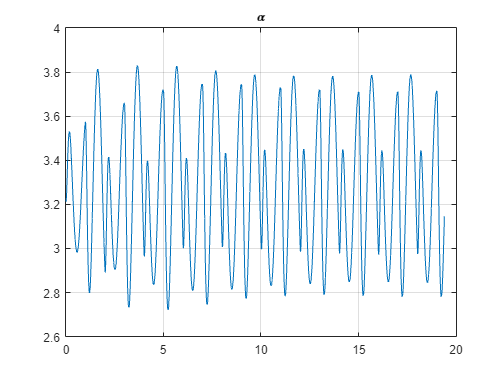

plot(t_esp81,alpha_esp81)
title('\alpha')
grid("on")

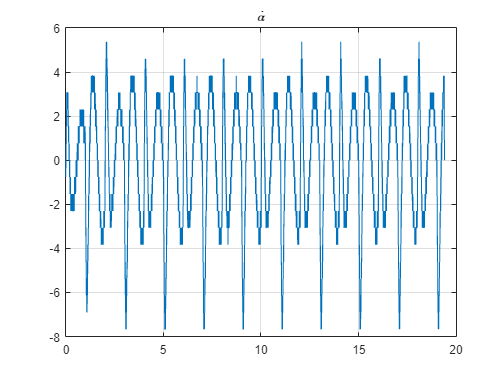

alpha_d_esp81(1,length(alpha_d_esp81)+1) = 0;
plot(t_esp81,alpha_d_esp81)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

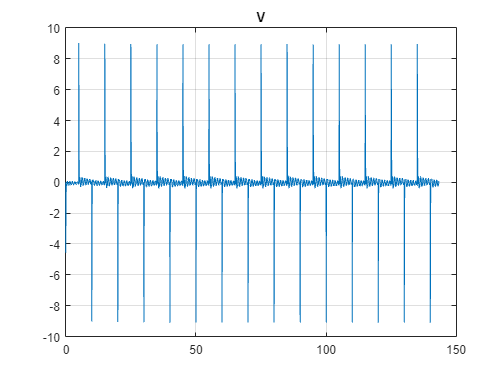

% Esperimento: 82

% Estraggo i dati dal file dell'esperimento
esp82_struct = load('esp82');
esp82 = cell2mat(struct2cell(esp82_struct));
t_esp82 = esp82(1,:);
voltage_esp82 = esp82(2,:);
theta_esp82 = esp82(3,:);
alpha_esp82 = esp82(4,:);
theta_ref_esp82 = esp82(5,:);
% Calcolo le velocità angolari:
theta_d_esp82 = diff(theta_esp82)/step_size;
alpha_d_esp82 = diff(alpha_esp82)/step_size;
% Plot
plot(t_esp82,voltage_esp82)
title('V')
grid("on")

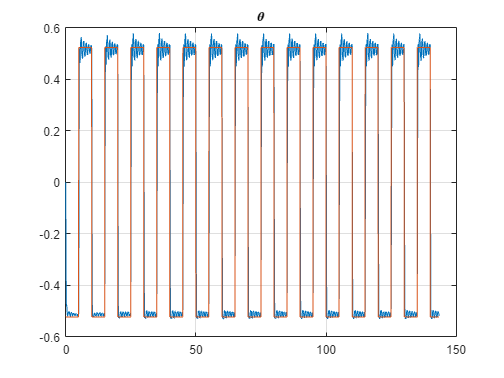


plot(t_esp82,theta_esp82)
hold on
plot(t_esp82,theta_ref_esp82)
hold off
title('\theta')
grid("on")

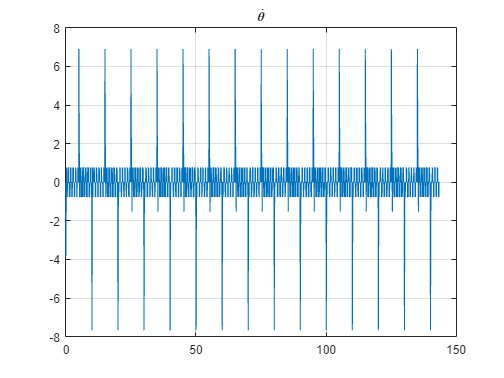

theta_d_esp82(1,length(theta_d_esp82)+1) = 0;
plot(t_esp82,theta_d_esp82)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

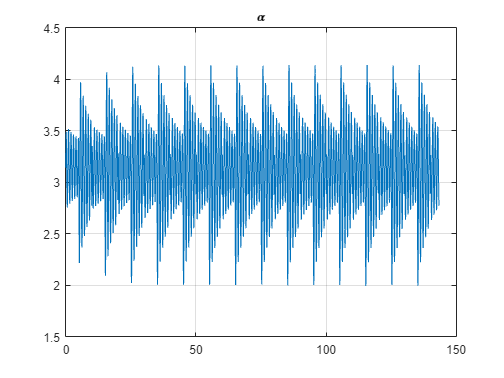

plot(t_esp82,alpha_esp82)
title('\alpha')
grid("on")

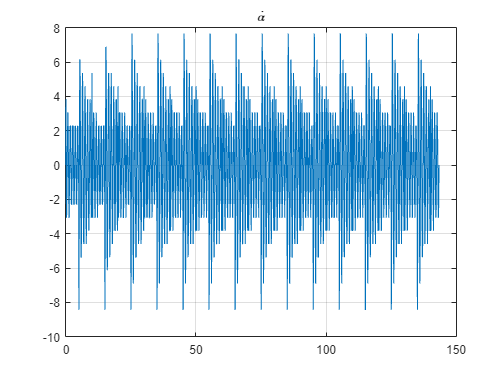

alpha_d_esp82(1,length(alpha_d_esp82)+1) = 0;
plot(t_esp82,alpha_d_esp82)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

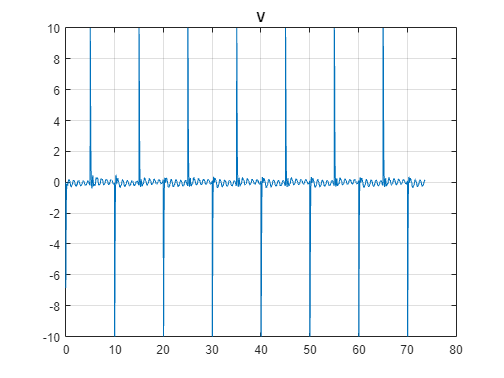

% Esperimento: 83

% Estraggo i dati dal file dell'esperimento
esp83_struct = load('esp83');
esp83 = cell2mat(struct2cell(esp83_struct));
t_esp83 = esp83(1,:);
voltage_esp83 = esp83(2,:);
theta_esp83 = esp83(3,:);
alpha_esp83 = esp83(4,:);
theta_ref_esp83 = esp83(5,:);
% Calcolo le velocità angolari:
theta_d_esp83 = diff(theta_esp83)/step_size;
alpha_d_esp83 = diff(alpha_esp83)/step_size;
% Plot
plot(t_esp83,voltage_esp83)
title('V')
grid("on")

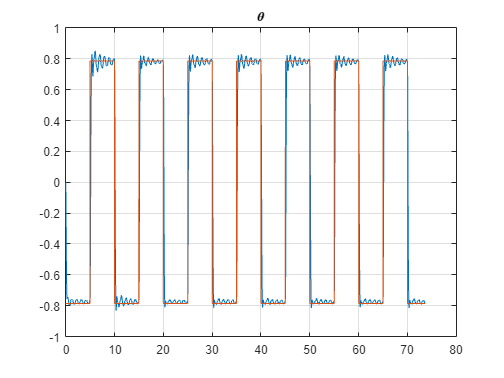


plot(t_esp83,theta_esp83)
hold on
plot(t_esp83,theta_ref_esp83)
hold off
title('\theta')
grid("on")

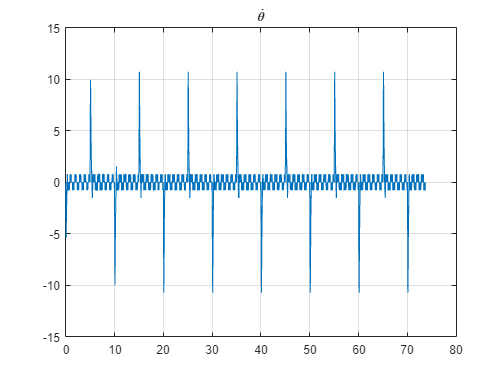

theta_d_esp83(1,length(theta_d_esp83)+1) = 0;
plot(t_esp83,theta_d_esp83)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

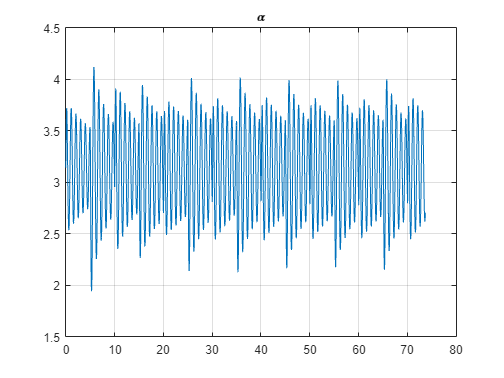

plot(t_esp83,alpha_esp83)
title('\alpha')
grid("on")

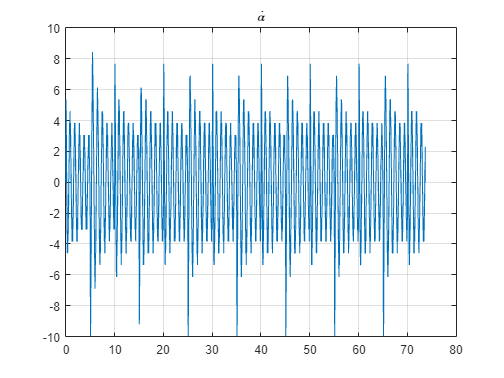

alpha_d_esp83(1,length(alpha_d_esp83)+1) = 0;
plot(t_esp83,alpha_d_esp83)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

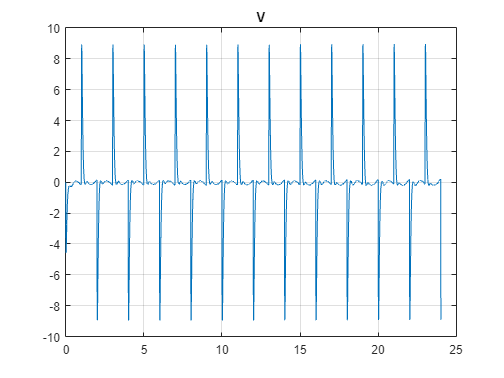

% Esperimento: 84

% Estraggo i dati dal file dell'esperimento
esp84_struct = load('esp84');
esp84 = cell2mat(struct2cell(esp84_struct));
t_esp84 = esp84(1,:);
voltage_esp84 = esp84(2,:);
theta_esp84 = esp84(3,:);
alpha_esp84 = esp84(4,:);
theta_ref_esp84 = esp84(5,:);
% Calcolo le velocità angolari:
theta_d_esp84 = diff(theta_esp84)/step_size;
alpha_d_esp84 = diff(alpha_esp84)/step_size;
% Plot
plot(t_esp84,voltage_esp84)
title('V')
grid("on")

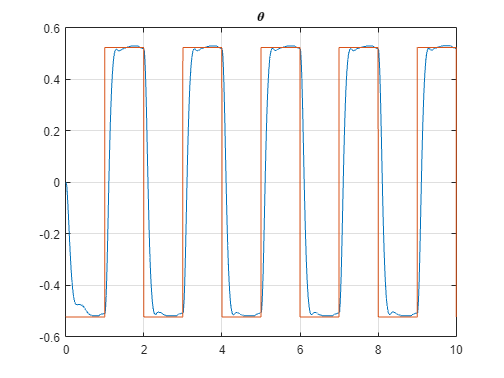


plot(t_esp84,theta_esp84)
hold on
plot(t_esp84,theta_ref_esp84)
hold off
title('\theta')
grid("on")
xlim([0 10])

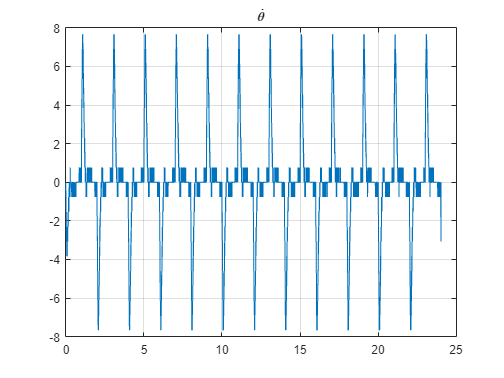

theta_d_esp84(1,length(theta_d_esp84)+1) = 0;
plot(t_esp84,theta_d_esp84)
title('$\dot{\theta}$','Interpreter','latex')
grid("on")

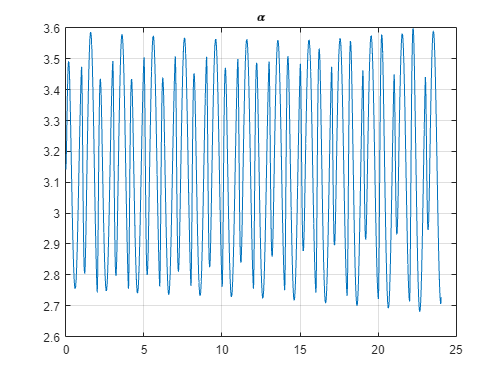

plot(t_esp84,alpha_esp84)
title('\alpha')
grid("on")

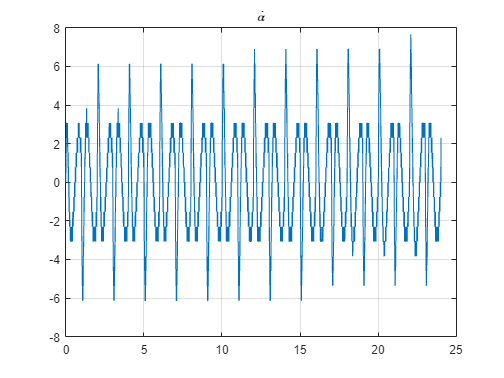

alpha_d_esp84(1,length(alpha_d_esp84)+1) = 0;
plot(t_esp84,alpha_d_esp84)
title('$\dot{\alpha}$','Interpreter','latex')
grid("on")

% Salvare tutte le varabili
% cd ..\Compensator_Alberto\alpha_d_esp
% save('alpha_d_esp71','alpha_d_esp71')
% save('alpha_d_esp72','alpha_d_esp72')
% save('alpha_d_esp73','alpha_d_esp73')
% save('alpha_d_esp74','alpha_d_esp74')
% save('alpha_d_esp75','alpha_d_esp75')
% save('alpha_d_esp76','alpha_d_esp76')
% save('alpha_d_esp77','alpha_d_esp77')
% save('alpha_d_esp78','alpha_d_esp78')
% save('alpha_d_esp79','alpha_d_esp79')
% save('alpha_d_esp80','alpha_d_esp80')
% save('alpha_d_esp81','alpha_d_esp81')
% save('alpha_d_esp82','alpha_d_esp82')
% save('alpha_d_esp83','alpha_d_esp83')
% save('alpha_d_esp84','alpha_d_esp84')
% cd ..
% cd ..\Compensator_Alberto\alpha_esp
% save('alpha_esp71','alpha_esp71')
% save('alpha_esp72','alpha_esp72')
% save('alpha_esp73','alpha_esp73')
% save('alpha_esp74','alpha_esp74')
% save('alpha_esp75','alpha_esp75')
% save('alpha_esp76','alpha_esp76')
% save('alpha_esp77','alpha_esp77')
% save('alpha_esp78','alpha_esp78')
% save('alpha_esp79','alpha_esp79')
% save('alpha_esp80','alpha_esp80')
% save('alpha_esp81','alpha_esp81')
% save('alpha_esp82','alpha_esp82')
% save('alpha_esp83','alpha_esp83')
% save('alpha_esp84','alpha_esp84')
% cd ..
% cd ..\Compensator_Alberto\theta_d_esp
% save('theta_d_esp71','theta_d_esp71')
% save('theta_d_esp72','theta_d_esp72')
% save('theta_d_esp73','theta_d_esp73')
% save('theta_d_esp74','theta_d_esp74')
% save('theta_d_esp75','theta_d_esp75')
% save('theta_d_esp76','theta_d_esp76')
% save('theta_d_esp77','theta_d_esp77')
% save('theta_d_esp78','theta_d_esp78')
% save('theta_d_esp79','theta_d_esp79')
% save('theta_d_esp80','theta_d_esp80')
% save('theta_d_esp81','theta_d_esp81')
% save('theta_d_esp82','theta_d_esp82')
% save('theta_d_esp83','theta_d_esp83')
% save('theta_d_esp84','theta_d_esp84')
% cd ..
% cd ..\Compensator_Alberto\theta_esp
% save('theta_esp71','theta_esp71')
% save('theta_esp72','theta_esp72')
% save('theta_esp73','theta_esp73')
% save('theta_esp74','theta_esp74')
% save('theta_esp75','theta_esp75')
% save('theta_esp76','theta_esp76')
% save('theta_esp77','theta_esp77')
% save('theta_esp78','theta_esp78')
% save('theta_esp79','theta_esp79')
% save('theta_esp80','theta_esp80')
% save('theta_esp81','theta_esp81')
% save('theta_esp82','theta_esp82')
% save('theta_esp83','theta_esp83')
% save('theta_esp84','theta_esp84')
% cd ..
% cd ..\Compensator_Alberto\t_esp
% save('t_esp71','t_esp71')
% save('t_esp72','t_esp72')
% save('t_esp73','t_esp73')
% save('t_esp74','t_esp74')
% save('t_esp75','t_esp75')
% save('t_esp76','t_esp76')
% save('t_esp77','t_esp77')
% save('t_esp78','t_esp78')
% save('t_esp79','t_esp79')
% save('t_esp80','t_esp80')
% save('t_esp81','t_esp81')
% save('t_esp82','t_esp82')
% save('t_esp83','t_esp83')
% save('t_esp84','t_esp84')
% cd ..
% cd ..\Compensator_Alberto\voltage_esp
% save('voltage_esp71','voltage_esp71')
% save('voltage_esp72','voltage_esp72')
% save('voltage_esp73','voltage_esp73')
% save('voltage_esp74','voltage_esp74')
% save('voltage_esp75','voltage_esp75')
% save('voltage_esp76','voltage_esp76')
% save('voltage_esp77','voltage_esp77')
% save('voltage_esp78','voltage_esp78')
% save('voltage_esp79','voltage_esp79')
% save('voltage_esp80','voltage_esp80')
% save('voltage_esp81','voltage_esp81')
% save('voltage_esp82','voltage_esp82')
% save('voltage_esp83','voltage_esp83')
% save('voltage_esp84','voltage_esp84')
% cd ..